f = 10e8;
er1 = 4;
ur1 = 4;
e0 = 8.87e-12;
u0 = 1.67e-7;
beta1 = (2*pi.*f)*sqrt(e0*er1*u0*ur1);
n1 = sqrt((u0*ur1)/(e0*er1));
theta_i = pi/3;
x = 0:0.01:1;
z = 0:0.01:1;
y = 0:0.01:1;

Eix = zeros(101, 101);
Eiy = zeros(101, 101);
Eiz = zeros(101, 101);

Erx = zeros(101, 101);
Ery = zeros(101, 101);
Erz = zeros(101, 101);

Hix = zeros(101, 101);
Hiy = zeros(101, 101);
Hiz = zeros(101, 101);

Hrx = zeros(101, 101);
Hry = zeros(101, 101);
Hrz = zeros(101, 101);

E10 = 2;

for n=1:1:101
    for m=1:1:101
       Eiy(n, m) = E10.*exp(-1i*(beta1.*sin(theta_i).*x(n) + ...
           beta1.*cos(theta_i).*z(m)));
       Ery(n, m) = -E10.*exp(-1i*(beta1.*sin(theta_i).*x(n) - ...
           beta1.*cos(theta_i).*z(m)));
       Hix(n, m) = -cos(theta_i).*(E10/n1).*exp(-1i*(beta1.*sin(theta_i).*x(n) + ...
           beta1.*cos(theta_i).*z(m)));
       Hiz(n, m) = sin(theta_i).*(E10/n1).*exp(-1i*(beta1.*sin(theta_i).*x(n) + ...
           beta1.*cos(theta_i).*z(m)));
       Hrx(n, m) = -cos(theta_i).*(E10/n1).*exp(-1i*(beta1.*sin(theta_i).*x(n) - ...
           beta1.*cos(theta_i).*z(m)));
       Hrz(n, m) = -sin(theta_i).*(E10/n1).*exp(-1i*(beta1.*sin(theta_i).*x(n) - ...
           beta1.*cos(theta_i).*z(m)));
       %parallel polarization
       Eix(n, m) = cos(theta_i).*E10.*exp(-1i*(beta1.*sin(theta_i).*x(n) + ...
           beta1.*cos(theta_i).*z(m)));
       Eiz(n, m) = -sin(theta_i).*E10.*exp(-1i*(beta1.*sin(theta_i).*x(n) + ...
           beta1.*cos(theta_i).*z(m)));
       Hiy(n, m) = (E10/n1).*exp(-1i*(beta1.*sin(theta_i).*x(n) + ...
           beta1.*cos(theta_i).*z(m)));
       Erx(n, m) = -cos(theta_i).*E10.*exp(-1i*(beta1.*sin(theta_i).*x(n) - ...
           beta1.*cos(theta_i).*z(m)));
       Erz(n, m) = -sin(theta_i).*E10.*exp(-1i*(beta1.*sin(theta_i).*x(n) - ...
           beta1.*cos(theta_i).*z(m)));
       Hry(n, m) = (E10/n1).*exp(-1i*(beta1.*sin(theta_i).*x(n) - ...
           beta1.*cos(theta_i).*z(m)));
    end
end

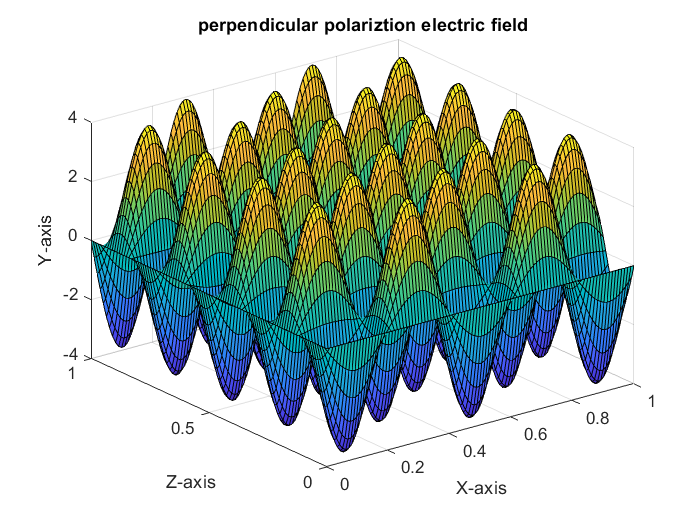

surf(x, z, real(Ery + Eiy));
title("perpendicular polariztion electric field")
xlabel("X-axis")
ylabel("Z-axis")
zlabel("Y-axis")

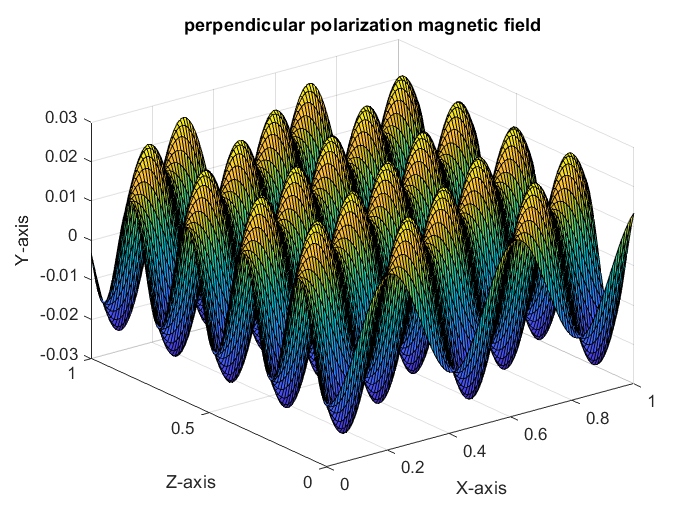

surf(x, z, real(Hix + Hrx + Hiz + Hrz));
title("perpendicular polarization magnetic field")
xlabel("X-axis")
ylabel("Z-axis")
zlabel("Y-axis")

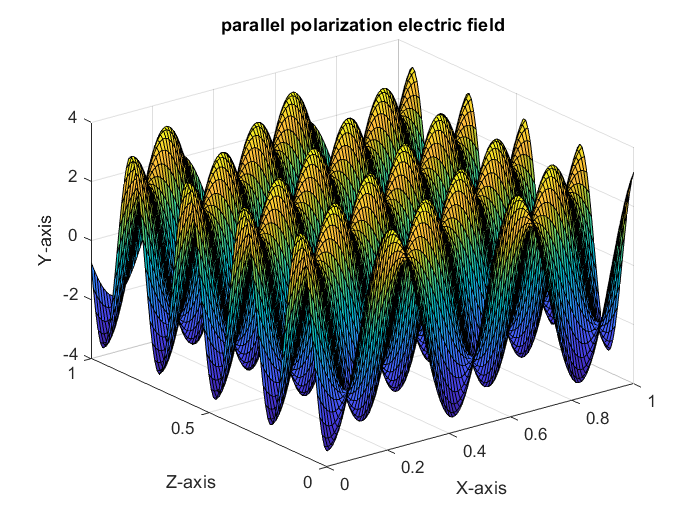

surf(x, z, real(Eix + Erx + Eiz + Erz));
title("parallel polarization electric field")
xlabel("X-axis")
ylabel("Z-axis")
zlabel("Y-axis")

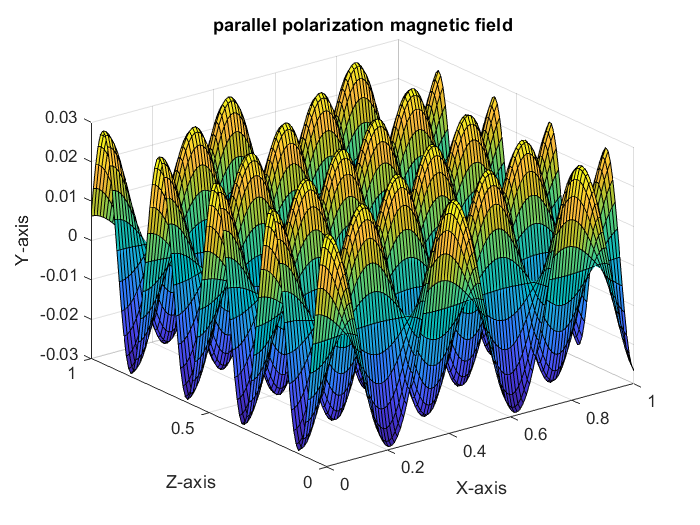

surf(x, z, real(Hiy + Hry));
title("parallel polarization magnetic field")
xlabel("X-axis")
ylabel("Z-axis")
zlabel("Y-axis")